# Homework 2: One-layer perceptron


$$\underline{x}^{(\mu)}=[x_1^{(\mu)}, x_2^{(\mu)}]^T$$



$$t^{\mu}=\pm1$$


Start by normalizing the data by centering each of the two input components and normalizing their respective variances to 1.

Your task is to train a perceptron with one fully-connected hidden layer, two input terminals and one output unit. Use the following network layout:

clc
clear
syms x
training_set = readmatrix("training_set.csv");
validation_set = readmatrix("validation_set.csv");
g = tanh(x);
eta = 0.05;
N = 2;
epoch_n = 1000;
error_criteria = 0.12;

## Preprocessing

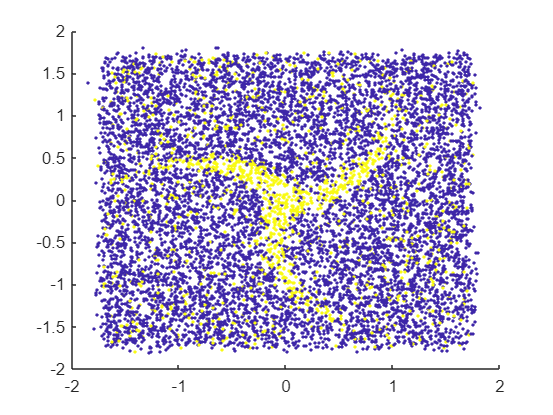

train_input_raw = training_set(:,1:2);
train_input = normalize(train_input_raw)';      % [2x10000]
target = training_set(:,3);                     % [10000x1]
figure
scatter(train_input(1,:),train_input(2,:),[],target,'.')

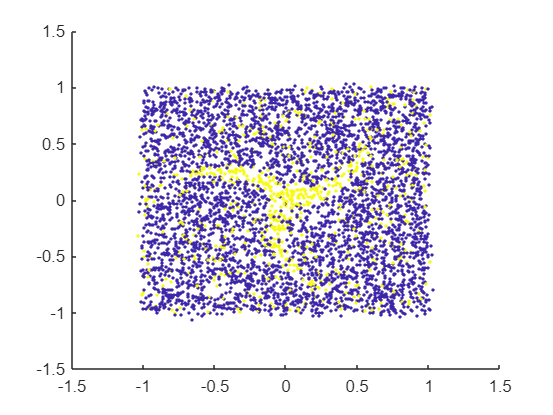

p = size(train_input,2);

figure
validation_input = validation_set(:,1:2)';      % [2x5000]
validation_target = validation_set(:,3);        % [5000x1]
scatter(validation_input(1,:),validation_input(2,:),[],validation_target,'.')

p_val = size(validation_input,2);

## Initialization

Different number of hidden neurons in the hidden layer.

M = 4; 
w = normrnd(0, 1/M, [M,2]);     % [Mx2] w_jk
theta = zeros([M,1]);           % [Mx1] theta_j
W = normrnd(0, 1/M, [1, M]);    % [1xM] W_ij i=1
Theta = 0;
V = zeros([M,1]);               % [Mx1] V_j
Out = 0;
H_train = [];
H_val = [];

## Set energy function

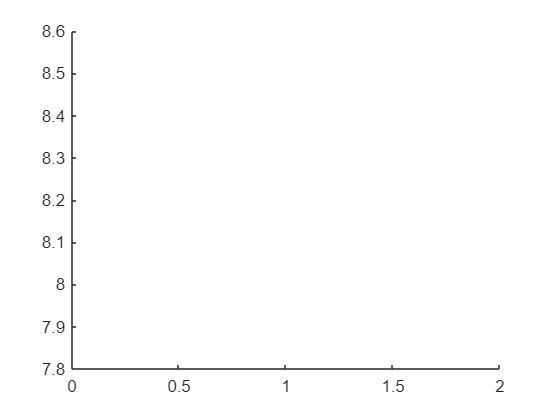

figure
hold on
H_train(end+1) = energy(W, w, Theta, theta, train_input, target);
H_val(end+1) = energy(W, w, Theta, theta, validation_input, validation_target);
plot(1:length(H_train),log(H_train))
plot(1:length(H_val),log(H_val))

## Training

for ep=1:epoch_n
    for nu = 1 : p
        mu = randi([1,p]);
        x_mu = train_input(:,mu); % randomly pick an input from training set
        t_mu = target(mu);
    
        % propagate forward
        b_mu = w*x_mu-theta;    % [3x1]
        V = tanh(b_mu);         % activation function g = tanh()
        B_mu = W*V-Theta;  % scalar
        Out = tanh(B_mu);       % scalar
        % end of propagate forward
    
        % back propagation
        %% Calculate Delta
        Delta = (target(mu) - Out) * eval(subs(diff(g), B_mu));
       
        %% Calculate delta
        delta = Delta * W'.* eval(subs(diff(g), b_mu));
        

        %% update W and w
        delta_w = eta * delta * x_mu';
        delta_W = eta * Delta * V';

        W = W + delta_W;
        w = w + delta_w;
        
        %% update Theta
        delta_Theta = -eta * Delta;
        Theta = Theta + delta_Theta;
    
        %% update theta
        delta_theta = -eta*delta;
        theta = theta + delta_theta; 
        % end of back propagation
    end
    W
    w
    H_train(end+1) = energy(W, w, Theta, theta, train_input, target);
    H_val(end+1) = energy(W, w, Theta, theta, validation_input, validation_target);
    
    plot(1:length(H_train),log(H_train))
    plot(1:length(H_val),log(H_val))
    legend('H\_train','H\_val')

    b = w*validation_input-theta;
    V = tanh(b);
    B = W*V-Theta;
    C = 1/(2*p_val)*sum(abs(validation_target'-sign(B)));

    if C < error_criteria
        disp('Classification error criteria is met');
        disp(['Epoch: ',num2str(ep),' C: ',num2str(C)])
        break
    else
        disp(['Epoch: ',num2str(ep),' C: ',num2str(C)])
    end
end

W =    -0.0093   -0.0021    0.0006    0.0058


w =    -0.0073   -0.0250
    0.0100    0.0897
    0.0106    0.1149
   -0.1123    0.0406


Epoch: 1 C: 0.1516


W =     0.0053    0.0154    0.0141   -0.0234


w =     0.0022   -0.0152
    0.0235    0.0517
    0.0237    0.0665
   -0.0480    0.0319


Epoch: 2 C: 0.1516


W =     0.0032   -0.0259   -0.0310   -0.0010


w =     0.0033   -0.0066
   -0.0026    0.0473
   -0.0053    0.0565
   -0.0215   -0.0020


Epoch: 3 C: 0.1516


## Validation

b = w*validation_input-theta
V = tanh(b)
B = W*V-Theta
C = 1/(2*p_val)*sum(abs(validation_target'-sign(B)))

## Plot H

figure
hold on
plot(1:length(H_train),log(H_train))
plot(1:length(H_val,log(H_val)))
legend('H\_train','H\_val')
hold off

function Out = fd_prop(W, w, Theta, theta, x)
    b_mu = w * x - theta;    % [Mx1]
    V = tanh(b_mu);         % activation function g = tanh()
    B_mu = W * V - Theta;  % scalar
    Out = tanh(B_mu);       % scalar
end

function H = energy(W, w, Theta, theta, input_set, target_set)
    H = 0;
    for mu = 1:size(input_set, 2)
        Out = fd_prop(W,w,Theta,theta,input_set(:,mu));
        H = H + (target_set(mu)-Out)^2;
    end
    H = H * 0.5;
end